# 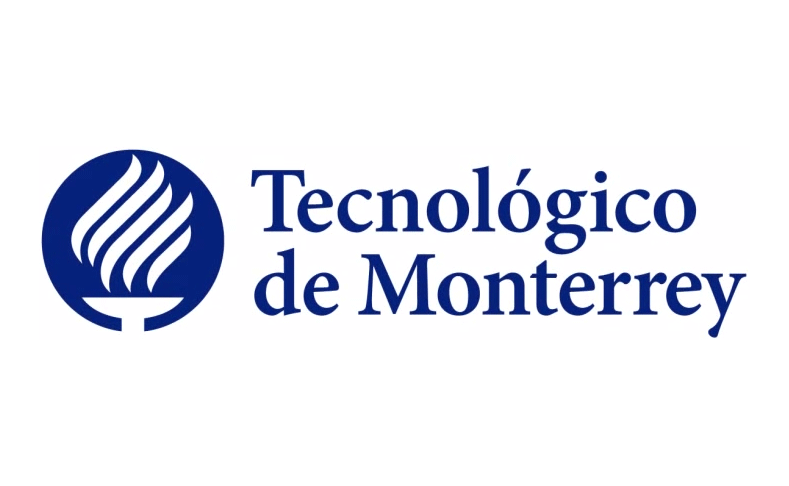

# Plantilla Optimización por Superficie de Respuesta

Desarrollador: Prof. Rodolfo Salazar Peña

clear
clc

## Diseño Experimental de Composición Central

Introduzca el punto central (0,0) en variables naturales:

X01=85;X02=175;
Center=[X01 X02];

Introduzca el punto un "paso" hacia el frente (1,1) para ambos factores en variables naturales:

X11=90;X12=180;
PointForward=[X11 X12];

Diseño de composición central

Wide=PointForward-Center;
xbis=[-1 -1; -1 1; 1 -1; 1 1; 0 0; sqrt(2)*[1 0; -1 0; 0 1; 0 -1]];

epsilon=Wide.*xbis+Center

epsilon =    80.0000  170.0000
   80.0000  180.0000
   90.0000  170.0000
   90.0000  180.0000
   85.0000  175.0000
   92.0711  175.0000
   77.9289  175.0000
   85.0000  182.0711
   85.0000  167.9289


x=[-1 -1; -1 1; 1 -1; 1 1; zeros(5,2); sqrt(2)*[1 0; -1 0; 0 1; 0 -1]];

## Carga de archivo

- Cargue el archivo con los datos experimentales de acuerdo al diseño de composición central. 

- No altere las variables codificadas de las primeras dos columnas de la plantilla original, solo la tercera columna con los valores de respuesta en variables naturales.

- Cargue el nombre del archivo derivado de la plantilla con su extensión. Por ejemplo: `Plantilla_Diseno_Composicion_Central.csv`

archivo="Plantilla_Diseno_Composicion_Central.csv";
data=readtable(archivo)

data = 13×3 table
     Var1       Var2      Var3
    _______    _______    ____

         -1         -1    76.5
         -1          1      77
          1         -1      78
          1          1    79.5
          0          0    79.9
          0          0    80.3
          0          0      80
          0          0    79.7
          0          0    79.8
     1.4142          0    78.4
    -1.4142          0    75.6
          0     1.4142    78.5
          0    -1.4142      77


y = data.Var3;
n=length(y);
[X1,X2]=meshgrid(-1.5:0.1:1.5);

## Ajuste a Modelos de Primer y Segundo Orden

### Diseño de primer orden

Modelo de Primer Orden: $\hat{y}=\beta_0+\beta_1x_1+\beta_2x_2$

Desea ejecutar el diseño de primer orden

   78.4769    0.9950    0.5152



Grado de ajuste modelo de primer orden R^2=0.3494


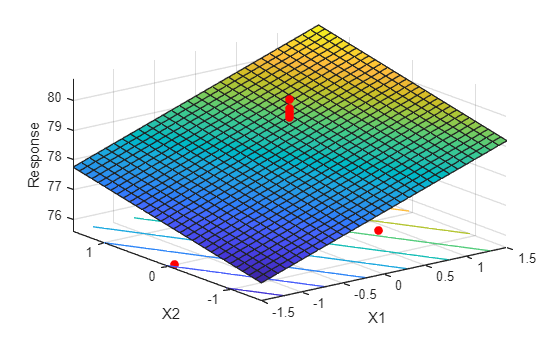

firstorder=true;
if firstorder
    [b1,~,~,~,stats1]=regress(y,[ones(n,1) x]);
    disp('Valores de ajuste beta')
    disp(b1.')
    disp(['Grado de ajuste modelo de primer orden R^2=' num2str(stats1(1))])
    Z1 = b1(1) + b1(2)*X1 + b1(3)*X2;
    figure
    responsesurface(X1,X2,Z1,x,y)
end

### Diseño de segundo orden

Modelo de Segundo Orden: $\hat{y}=\beta_0+\beta_1x_1+\beta_2x_2+\beta_3x_1^2+\beta_4x_2^2+\beta_5x_1x_2$

[b2,~,~,~,stats2]=regress(y,[ones(n,1) x x.^2 x(:,1).*x(:,2)]);
disp(b2.')

   79.9400    0.9950    0.5152   -1.3762   -1.0012    0.2500



disp(['Grado de ajuste modelo de segundo orden R^2=' num2str(stats2(1))])

Grado de ajuste modelo de segundo orden R^2=0.98277


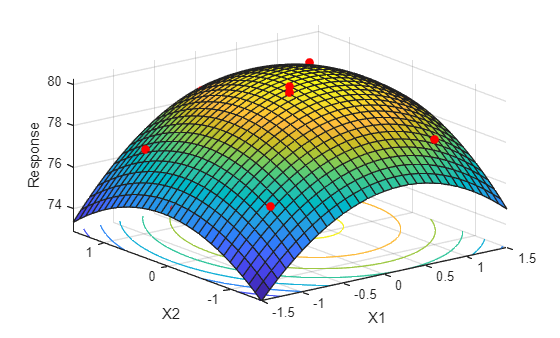

Z2=b2(1)+b2(2)*X1+b2(3)*X2+b2(4)*X1.^2+b2(5)*X2.^2+b2(6)*X1.*X2;
figure
responsesurface(X1,X2,Z2,x,y)

## Optimización

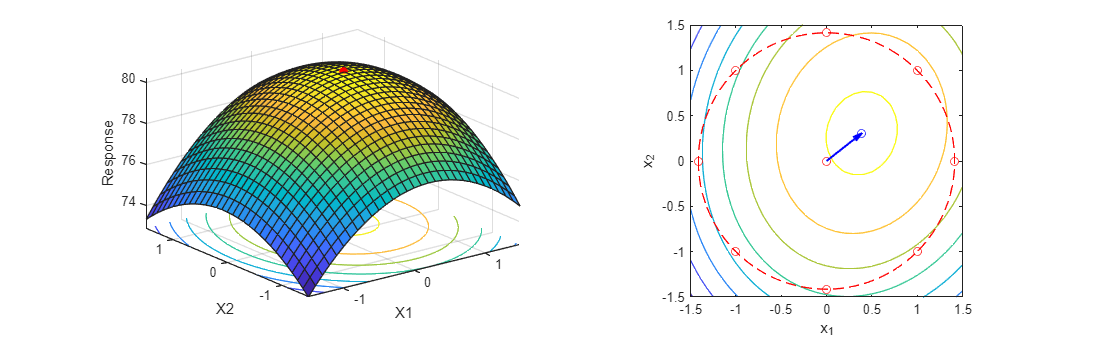

bb=b2(2:3);
B=[b2(4) b2(6)/2; b2(6)/2 b2(5)];
BB=B\bb;
x0=-BB/2;
y0=b2(1)-BB.'*bb/4;

figure
subplot(1,2,1)
responsesurface(X1,X2,Z2,x0.',y0)
subplot(1,2,2)
contour(X1, X2, Z2)
rectangle('Position',[-sqrt(2) -sqrt(2) 2*sqrt(2) 2*sqrt(2)],'LineStyle','--','EdgeColor','r','Curvature',[1 1])
axis equal
hold on
plot(x(:,1),x(:,2),'ro')
quiver(0, 0, x0(1), x0(2), 0, 'b', 'LineWidth', 1.5, 'MaxHeadSize', 0.8);
plot(x0(1), x0(2), 'bo');
xlabel('x_1')
ylabel('x_2')
hold off

fig=gcf;
fig.Position(3)=1120;

Valor de variables naturales que dan el punto crítico.

XX=Wide.'.*x0+Center'

XX =    86.9463
  176.5293


Valor de la variable de respuesta en el punto crítico.

y0

y0 = 80.2124

## Verificación de valores característicos

Valores característicos

eigenvalues=eig(B)

eigenvalues =    -1.4141
   -0.9634


if eigenvalues<0
    disp('The eigenvalues are negative, indicating a local maximum.');
elseif eigenvalues>0
    disp('The eigenvalues are not negative, indicating a local minimum.');
else
    disp('The eigenvalues are either nulls, positive or negative, indicating likely saddle point')
end

The eigenvalues are negative, indicating a local maximum.


## Referencias

[1] Douglas C. Montgomery. *Diseño y Análisis de Experimentos*. 3.a ed. México, D.F.: Grupo Editorial Iberoamérica, 1991.

[2] Richard A. Johnson, Irwin Miller y John Freund. *Miller & Freund’s Probability and Statistics for Engineers*. 9.a ed. Global Edition: Pearson Education, 2019.

function responsesurface(X1,X2,Z,x,y)
surfc(X1, X2, Z)
hold on
plot3(x(:,1),x(:,2),y,'ro','MarkerFaceColor','r')
hold off
xlabel('X1')
ylabel('X2')
zlabel('Response')
end
